## **Projekt Bild**

**Karolina Utsi & Theo Wikström**

**Theo - Kolla igenom alla punkter förutom 5 och skriv lite genomförande.**

**Karolina - Problembeskrivning, diskussion & 5an**

**Båda - kolla igenom koden kommentarer variabelnamn. **

### **Problembeskrivning**

Detta projekt behandlar fMRI (functional Magnetic Resonance Imaging) som studerar hjärnaktivitet genom att mäta den hemodynamiska responsen då en aktivitet utförs av en testperson.

Målet med projektet är att hitta en korrelation mellan en tidsserie av MRI bilder till aktiviteten som utförts av testpersonen, vilket i detta fall är en finger-tapping-uppgift som sker i block om 16 sekunder. Under projektets gång har filter, rörelsekorrigeringar och andra saker (?) utförts för att hitta en eventuella mönster och korrelationer med en förvantad signal HRF-signal (Hemodynamic Response Function).

### **Punkt 1**

I denna del av projektet används rå MRI-data i  `k-space`, vilket representerar signalen i frekvensdomänen. Datamängden var lagrad i en array med dimensionerna `[X,Y,Z,T]` där `X,Y,Z `beskriver de rumsliga dimensionerna (den spatiala bilden) och `T` representerar antalet tidssteg. I den givna datan består tidsdimensionen av 160 tidssteg eftersom en bild är tagen varannan sekund över ett 320 sekunders intervall.

Eftersom MRI-systemet mäter signalen i frekvensdomänen måste datan transformeras till spatialdomänen för att kunna visualiseras. Detta görs genom att använda en `invers Fast Fourier Transform (iFFT)` i tre dimensioner.

För varje tidssteg hämtas motsvarande k-space-data och omvandlas till en spatial bild med hjälp av en `iFFT`. Eftersom resultatet från Fouriertransformen innehåller komplexa värden används absolutvärdet för att få fram bildens intensitet.

De återskapade bilderna sparas i en 4D-array med samma dimensioner som ursprungsdatan. För att visualisera resultatet visas ett mittsnitt i z-led som en animation över alla tidssteg. På så sätt går det att se hur signalen förändras över tid i hjärnan.

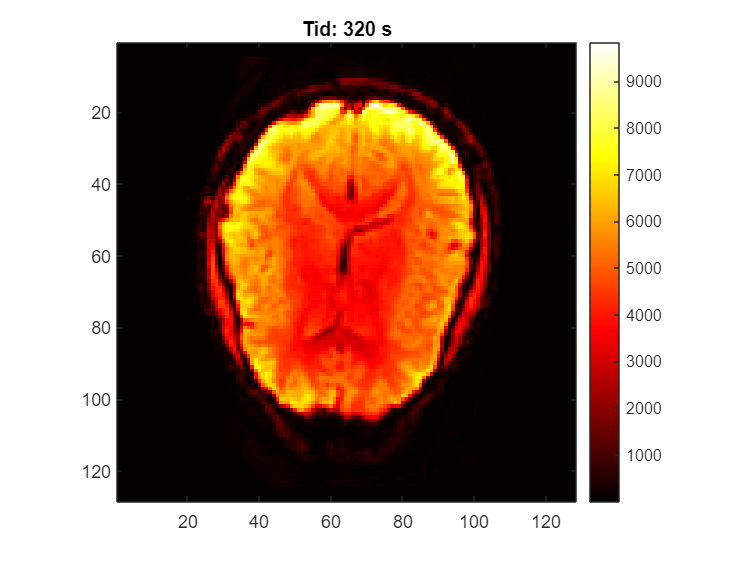

% Load raw k-space data
load('Data/rawData.mat');  

% Skapa 3D-bilder via iFFT
numTimepoints = size(kSpace,4);  
% Lagrar bilder 
img = zeros(size(kSpace));            

for t = 1:numTimepoints
    % plockar ut k-space vid tid t
    k0 = kSpace(:,:,:,t);             
    img(:,:,:,t) = abs(fftshift(ifftn(ifftshift(k0))));  
end

% Visar mittsnitt i z-led som animation
z_mid = round(size(img,3)/2);         

figure; 
for t = 1:numTimepoints
    imagesc(img(:,:,z_mid,t));
    colormap hot; 
    axis image; 
    colorbar;
    title(['Tid: ' num2str(t*2) ' s']);  
    pause(0.1);  % justera hastighet på animationen
end

### **Punkt 2**

I denna del av uppgiften korrigeras eventuella rörelseförändringar mellan mätningarna. Små rörelser kan uppstå under en MRI-mätning eftersom personen i skannern inte ligger helt stilla. Detta kan göra att bilderna inte är perfekt justerade mellan olika tidssteg och kan ge fel i den fortsatta analysen.

För att minska denna effekt används `image registration` i Matlab. Den första bilden väljs som referensbild och de efterföljande bilderna justeras så att de överensstämmer så bra som möjligt med referensen.

Justeringen görs med en `rigid transformation`, vilket innebär att bilderna endast får roteras och förskjutas utan att ändra form eller skala. För varje tidssteg beräknas en transformation som bäst matchar den aktuella bilden mot referensbilden. Denna transformation appliceras sedan på bilden för att skapa en korrigerad version.

I denna implementation utförs analysen på ett mittsnitt i z-led för att förenkla beräkningen. De korrigerade bilderna visualiseras därefter som en animation över tid för att kunna observera hur justeringen påverkar bildsekvensen.

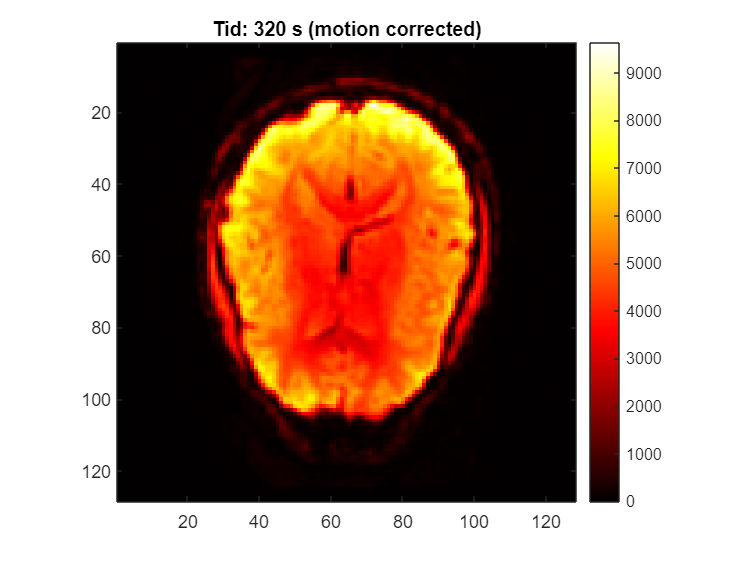


% Motion correction på mittsnitt i z-led
z_mid = round(size(img,3)/2);             % mitt i z-led
img_slice = squeeze(img(:,:,z_mid,:));    

% Nu görs motion correction bara i z led, hade kunnat
% göras på hela 3D volymen för en mer advancerad metod.
fixed = img_slice(:,:,1);                 % första bilden som referens
img_corrected = zeros(size(img_slice));   % Spara korrigerade bilder

% Skapa optimizer och metric
[optimizer, metric] = imregconfig('monomodal');  % passar bra för MRI

for t = 1:size(img_slice,3)
    moving = img_slice(:,:,t);
    
    % Rigid image registration
    tform = imregtform(moving, fixed, 'rigid', optimizer, metric);
    
    % Transformera och spara korrigerad bild
    img_corrected(:,:,t) = imwarp(moving, tform, 'OutputView', imref2d(size(fixed)));
end

% Visa animation av korrigerade bilder
figure;
for t = 1:size(img_corrected,3)
    imagesc(img_corrected(:,:,t));
    colormap hot;
    axis image;
    colorbar;
    title(['Tid: ' num2str(t*2) ' s (motion corrected)']);
    pause(0.10);
end

### **Punkt 3**

Här filtreras bilderna för att minska brus i datan. fMRI-data kan innehålla högfrekvent brus som kan påverka analysen och göra det svårare att identifiera hjärnaktivitet i senare steg av projektet.

För att reducera detta brus används ett 3D-gaussiskt lågpassfilter. Ett lågpassfilter dämpar höga frekvenser samtidigt som de lägre frekvenserna bevaras.

Filtreringen utförs i frekvensdomänen genom att multiplicera k-space-datan med det gaussiska filtret eftersom den datan redan är i frekvensplanet. Därefter används en invers Fouriertransform för att omvandla datan tillbaka till spatialdomänen och skapa den filtrerade bilden.

Resultatet sparas i en ny 4D-array och visualiseras genom att visa ett mittsnitt i z-led som en animation över tid.

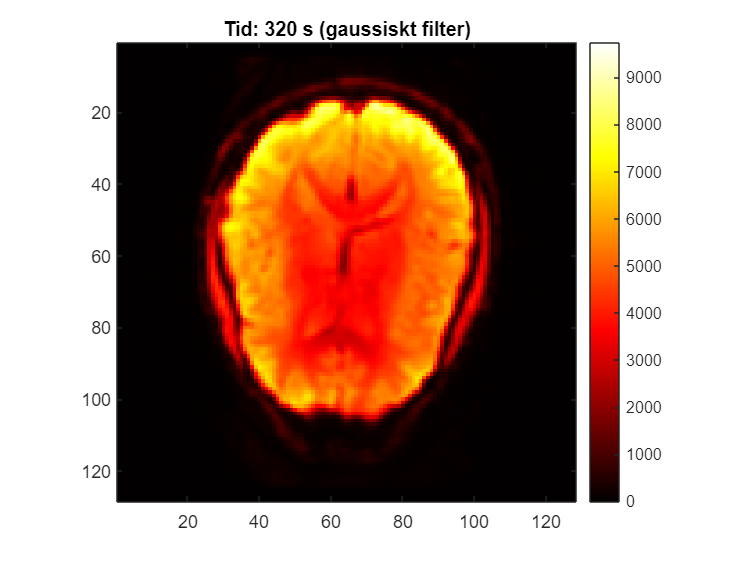

% Parametrar
numTimepoints = size(kSpace,4);       % antal tidssteg (160)
[X, Y, Z] = size(kSpace(:,:,:,1));

img_filtered = zeros(X,Y,Z,numTimepoints);  % 4D-array för bilder efter filtrering

% Skapa 3D-gaussiskt lågpassfilter
a = 0.3;  % lite större värde än tidigare
[x, y, z] = ndgrid(linspace(-0.5,0.5,X), linspace(-0.5,0.5,Y), linspace(-0.5,0.5,Z));
gaussFilter = exp(-(x.^2 + y.^2 + z.^2)/(2*a^2));

% Applicera filter i frekvensplanet och iFFT
for t = 1:numTimepoints
    k0 = kSpace(:,:,:,t);                 % rå k-space data
    kFilt = k0 .* gaussFilter;            % filtrera i frekvensplanet
    img_filtered(:,:,:,t) = abs(fftshift(ifftn(ifftshift(kFilt))));  % iFFT
end

% Animation av mittsnitt i z-led
z_mid = round(Z/2);                       
figure;
for t = 1:numTimepoints
    imagesc(img_filtered(:,:,z_mid,t));
    colormap hot;       
    axis image;
    colorbar;
    clim([0 max(img_filtered(:))]);  % fixar kontrasten så hjärnstrukturen syns bättre
    title(['Tid: ' num2str(t*2) ' s (gaussiskt filter)']);
    pause(0.05);
end

### **Punkt 4**

I denna del av projektet skapas en tidsvektor som representerar hjärnans förväntade aktiveringsnivå under experimentet. Testpersonen genomförde finger-tapping i block med fast periodtid över ett tidspann, och tidpunkterna för när aktiviteten startade och slutade används för att definiera en rå aktiveringssignal. Signalen har värdet 1 under aktivitet och 0 under vila.

För att bättre efterlikna den biologiska responsen i hjärnan används en responsfunktion `(HRF)`. Den råa aktiveringssignalen konvolveras med HRF, vilket ger en förväntad signal som tar hänsyn till hur blodflödet reagerar med viss fördröjning på hjärnaktivitet. Denna signal används sedan som modell för jämförelse med fMRI-data.

Resultatet visualiseras som en kurva över tid som visar den förväntade hjärnaktiveringen under hela mätningen. Denna signal kommer att bli underlag för att jämföra korrelation med voxeldatan.

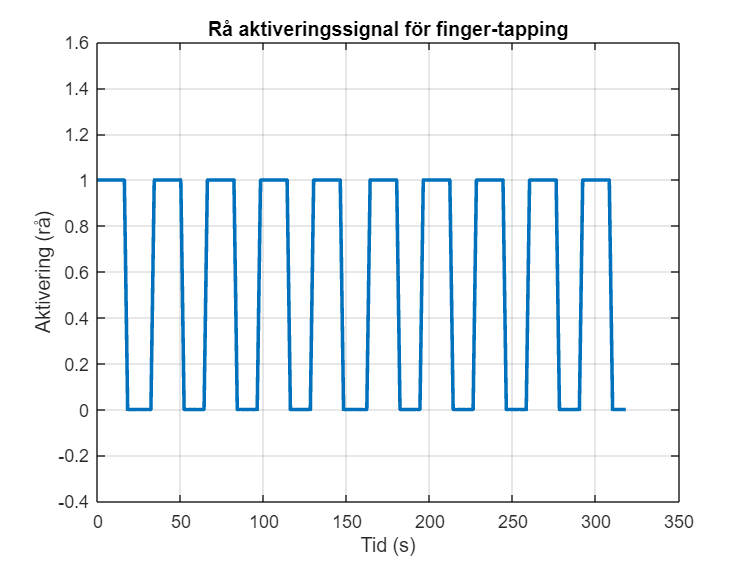

% Parametrar
numTimepoints = 160;
dt = 2;  % tidssteg i sekunder
time = (0:numTimepoints-1) * dt;  % tidsvektor för experimentet

% Finger-tapping-block och längd
blockStart = [0 32.4 64.8 97.2 129.7 162.1 194.5 226.9 259.3 291.7]; 
blockLength = 16;  % s

% Skapa rå aktivering: 0 = vila, 1 = aktivitet
raw_activation = zeros(1, numTimepoints);
for i = 1:length(blockStart)
    startIdx = find(time >= blockStart(i), 1, 'first');
    endIdx = find(time >= blockStart(i) + blockLength, 1, 'first');
    raw_activation(startIdx:endIdx) = 1;
end

% Plotad aktiveringssignal
figure;
plot(time, raw_activation, 'LineWidth', 2);
xlabel('Tid (s)');
ylabel('Aktivering (rå)');
title('Rå aktiveringssignal för finger-tapping');
ylim ([-0.4 1.6])
grid on;

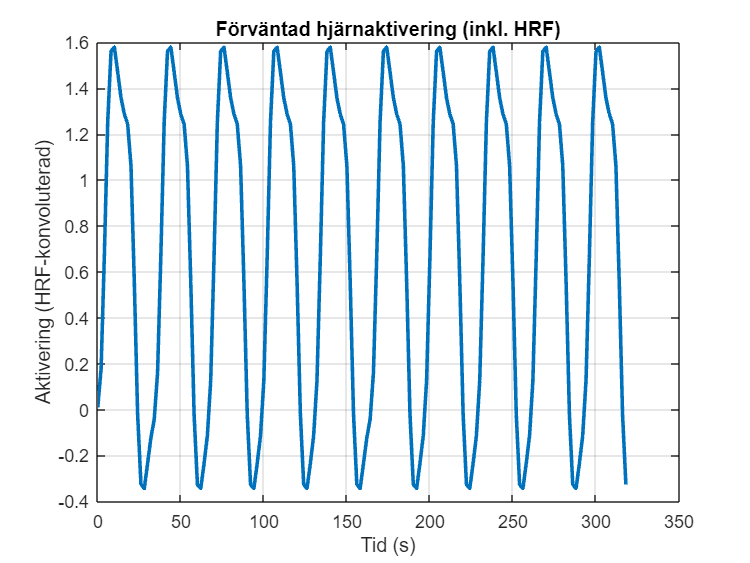


% Ladda HRF-filen 
hrfStruct = load('Data/hrf_1ms.mat');  

% Hämta variabelnamnet automatiskt
varName = fieldnames(hrfStruct);   
hrf = hrfStruct.(varName{1});      

% Skapa tidsvektor (samma som bilderna)
time = (0:numTimepoints-1)*dt; 

% Resample HRF till samma tidsupplösning
hrf_resampled = interp1((0:length(hrf)-1)/1000, hrf, time, 'linear', 0);

% Konvolvera signalen med HRF
activation_signal = conv(raw_activation, hrf_resampled);
activation_signal = activation_signal(1:numTimepoints);  % trimma till originalstorlek

% Visa konvolerad aktiveringssignal
figure;
plot(time, activation_signal, 'LineWidth', 2);
xlabel('Tid (s)');
ylabel('Aktivering (HRF-konvoluterad)');
title('Förväntad hjärnaktivering (inkl. HRF)');
grid on;

### **Punkt 5**

I denna del beräknas korrelationen mellan den förväntade aktiveringssignalen och tidsserien för varje voxel i hjärnan. Detta görs genom att först omforma 4D-datan till en 2D-matris där varje rad representerar en voxel över tid. Matlabfunktionen `corr` används sedan för att beräkna Pearsons korrelation mellan varje voxels signal och aktiveringssignalen.

För att visualisera detta skapades två figurer. I den första figuren visas signalerna i deras ursprungliga skala, där voxelns signal består av mycket brus. Signalen är väldigt liten och det finns mycket brus som inte filtrerats bort med det gaussiska lågpassfiltret. Detta kan bero på fysiskt brus, som andning, hjärtslag och små rörelser. Från figuren kan det därför bli svårt att tolka och se sambandet med aktiveringssignalen. 

För att försöka få en bättre bild över det eventuella sambandet normaliserades de båda signalerna med hjälp av `z-score`, vilket gör att de får samma skala och kan jämföras utifrån variationer över tid. Från den andra figuren kan vi delvis se ett samband mellan signalerna.

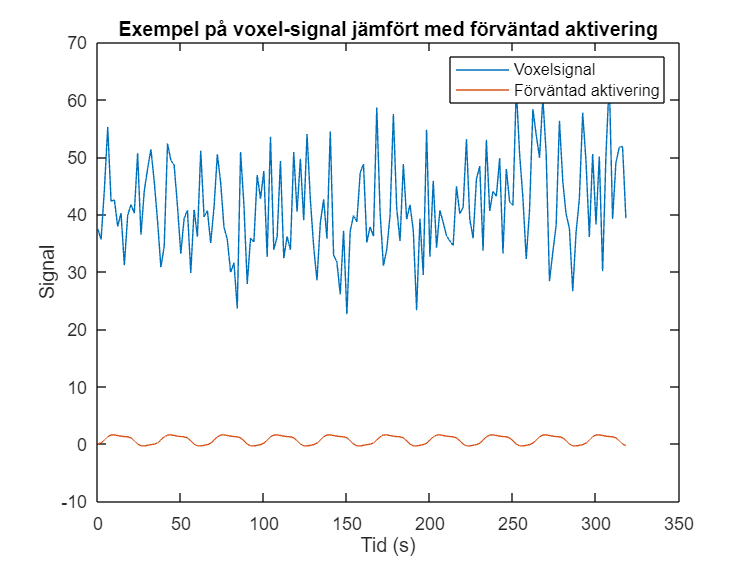

% Punkt 5 – Beräkna korrelation mellan voxlar och aktiveringssignal

% Omforma 4D-data till 2D (voxlar x tid)
[X,Y,Z,T] = size(img_filtered);
numVoxels = X*Y*Z;

fMRI_matrix = reshape(img_filtered, numVoxels, T);  % varje rad = voxel

% Beräkna korrelation mellan varje voxel och aktiveringssignalen
corr_vals = corr(fMRI_matrix', activation_signal');

% Omforma tillbaka till 3D
corr_3D = reshape(corr_vals, X, Y, Z);


% Visualisera ett exempel på voxel-signal

voxel_example = fMRI_matrix(5000,:);

figure;
plot(time, voxel_example);
hold on;
plot(time, activation_signal);
legend('Voxelsignal','Förväntad aktivering');
xlabel('Tid (s)');
ylabel('Signal');
title('Exempel på voxel-signal jämfört med förväntad aktivering');

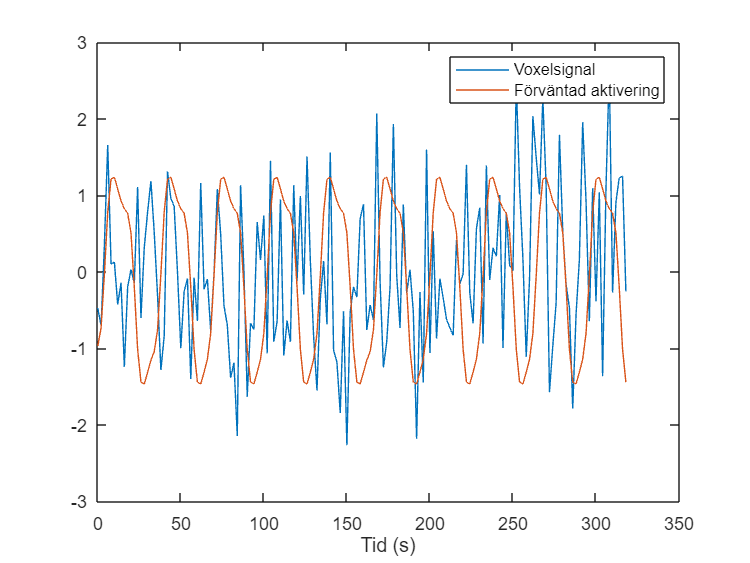

voxel_example = fMRI_matrix(5000,:);

figure
plot(time, zscore(voxel_example))
hold on
plot(time, zscore(activation_signal))
xlabel('Tid (s)');
legend('Voxelsignal','Förväntad aktivering')

### **Punkt 6**

I denna del analyseras hur väl voxel-signalerna överensstämmer med den förväntade aktiveringssignalen. Vi använder korrelation för att skapa en 3D-aktiveringskarta, utvärderar statistiken över korrelationsvärden och visar även hur frekvensanalys kan komplettera metoden.

Ett värde på 1 ger stark korrelation alltså hjärnans voxlar följer förväntat aktiveringsmönster. Ett värde på 0 ger ingen koppling och -1 ger värdet omvänd korrelation. Vi ser ljusa områden på varsin sida om hjärnan som förmodligen representerar att båda fingrarna har använts till experimentet. 

För den omvända korrelationen kan en eventuell slutsats vara "dagdrömscentret" som kommer att minska när en medveten övning utförs. De voxlar som ger ett negativt värde kan vara delar av detta dagdrömscenter som får "negativ" korrelation när testpersonen blir mer uppmärksam och blodet flödar ifrån det området.

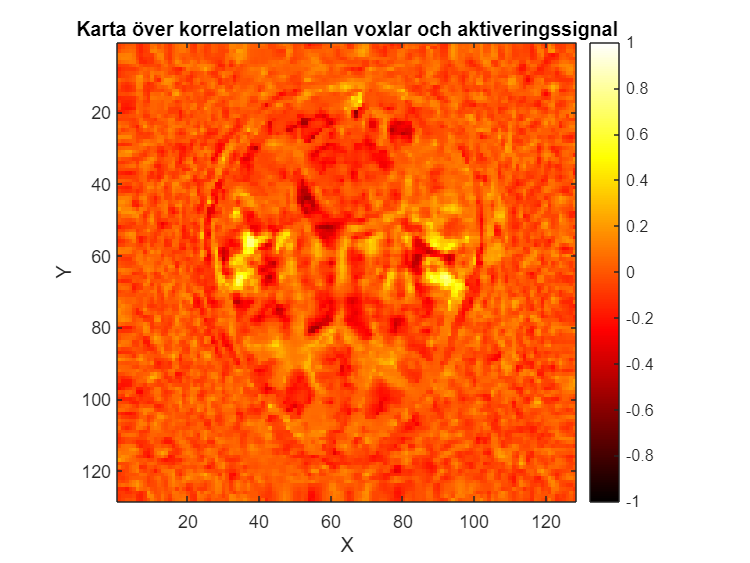

% Skapa 3D aktiveringskarta

% corr_3D kommer från punkt 5

z_mid = round(Z/2);

figure;
imagesc(corr_3D(:,:,z_mid));
colormap hot;
colorbar;
axis image;
caxis([-1 1]);

title('Karta över korrelation mellan voxlar och aktiveringssignal');
xlabel('X');
ylabel('Y');

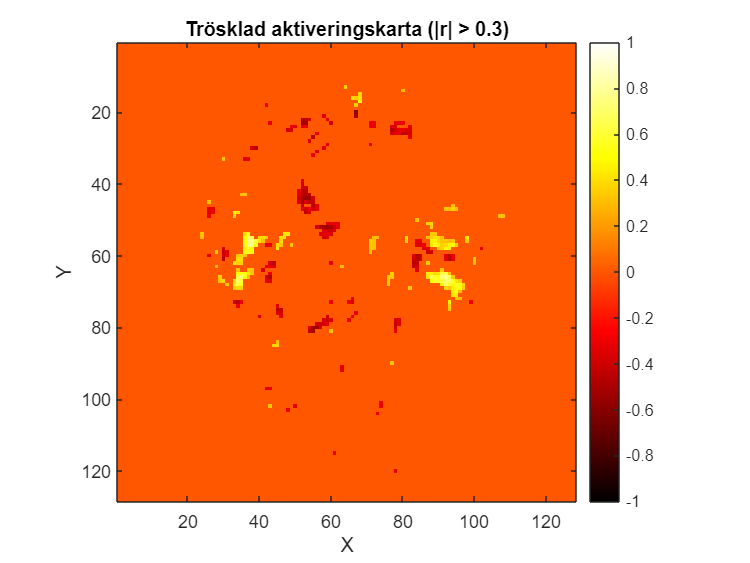



% Tröskla aktiveringskartan för tydligare resultat

threshold = 0.3;

activation_map = corr_3D;
activation_map(abs(corr_3D) < threshold) = 0;

figure;
imagesc(activation_map(:,:,z_mid));
colormap hot;
colorbar;
axis image;
caxis([-1 1]);

title(['Trösklad aktiveringskarta (|r| > ' num2str(threshold) ')']);
xlabel('X');
ylabel('Y');

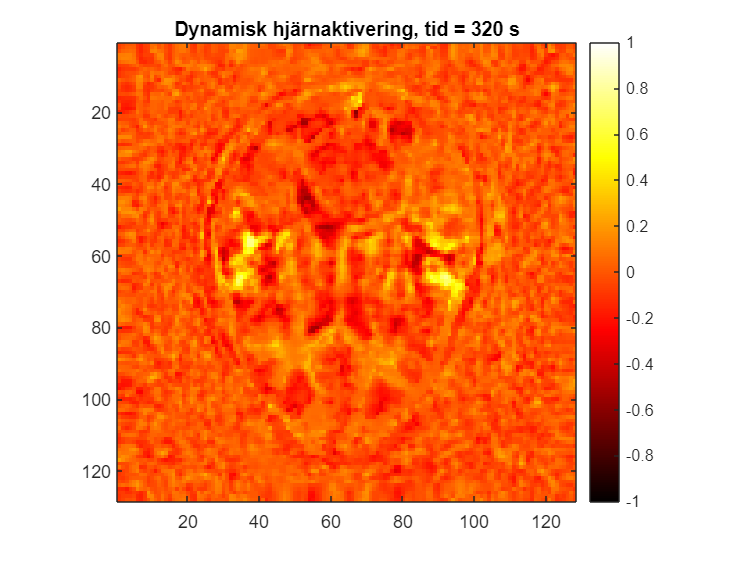

% ANIMATION
% Dynamisk visualisering av aktivering över tid
figure;

for t = 5:T   % börja vid 5 så korrelationen blir stabilare
    
    % korrelation upp till tidpunkt t
    corr_vals_t = corr(fMRI_matrix(:,1:t)', activation_signal(1:t)');
    
    % tillbaka till 3D
    corr_3D_t = reshape(corr_vals_t, X, Y, Z);
    
    % visa mittsnitt
    imagesc(corr_3D_t(:,:,z_mid));
    colormap hot;
    colorbar;
    axis image;
    caxis([-1 1]);
    
    title(['Dynamisk hjärnaktivering, tid = ' num2str(t*2) ' s']);
    
    pause(0.05);
end

**6.1**

Histogrammet visar att majoriteten av hjärnans voxlar har korrelationsvärden nära noll, vilket tyder på att de inte är relaterade till den förväntade aktiveringen. Ett mindre antal voxlar uppvisar hög korrelation, vilket indikerar hjärnregioner som aktiveras under finger-tapping-experimentet.

% Statistik över korrelationsvärden

corr_values = corr_3D(:);   % alla voxlar som en vektor

mean_corr = mean(corr_values);
std_corr = std(corr_values);
max_corr = max(corr_values);
min_corr = min(corr_values);

disp(['Mean correlation: ' num2str(mean_corr)])

Mean correlation: 0.002152


disp(['Std correlation: ' num2str(std_corr)])

Std correlation: 0.11511


disp(['Max correlation: ' num2str(max_corr)])

Max correlation: 0.9276


disp(['Min correlation: ' num2str(min_corr)])

Min correlation: -0.8422


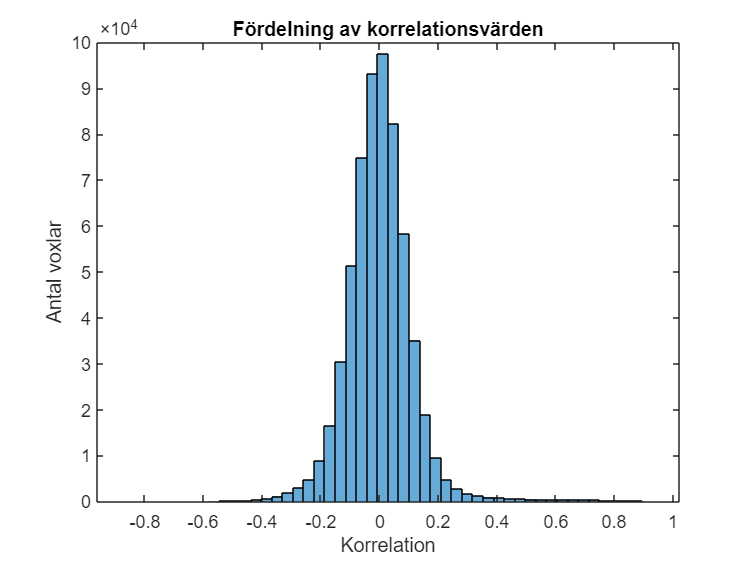


% Histogram över korrelationer
figure;
histogram(corr_values,50);
xlabel('Korrelation');
ylabel('Antal voxlar');
title('Fördelning av korrelationsvärden');

**6.2**

Filtreringen för uppgiften gör så att högfrekvent brus i bilderna minskas. Detta gör att voxelsignalerna blir mer stabila över tid. Det leder i sin tur till att korrelationsanalysen blir mer pålitlig eftersom att filtret försummar falska variationer i hjärnaktivitet. 

Lämplig filtering valdes genom att hitta en balans i filterbredden `a` som tar bort tillräckligt mycket brus men som inte gör bilden allt för suddig. Om filterbredden är för stor riskerar man att sudda ut strukturerna i bilden vilket inte ger ett bra resultat.

För korrelationsvärdena kan vi se i histogrammet att de flesta värdena ligger nära 0 och visar därför på ingen korrelation mellan voxlar och förväntad aktivering. Vi ser däremot ett fåtal värden som närmar sig ett vilket visar på stark korrelation. Detta represterar att enbart vissa delar av hjärnan aktiveras för att utföra finger-tapping. 

**6.3**

Här undersöktes om hjärnans voxlar reagerar i samma frekvens som den förväntade aktiveringssignalen, istället för att analysera korrelation i tidsdomänen. Genom en Fouriertransform på aktiveringssignalen identifierades den dominanta frekvensen, dvs frekvensen där signalen varierar mest.

Voxel-signalerna transformeras också till frekvensplanet och amplituden vid den dominanta frekvensen tas ut för varje voxel. Eftersom vi i exemplet analyserar en enskild voxel är det dock inte säkert att den ligger i ett område som påverkas starkt av finger-tapping, vilket kan göra resultaten mer osäkra.

Resultatet visualiseras som en 3D-karta, men jämfört med analysen i tidsdomänen blir spatiala mönster mindre tydliga. Detta beror på att frekvensanalysen endast visar hur mycket varje voxel varierar vid en viss frekvens och inte exakt när aktiviteten sker.

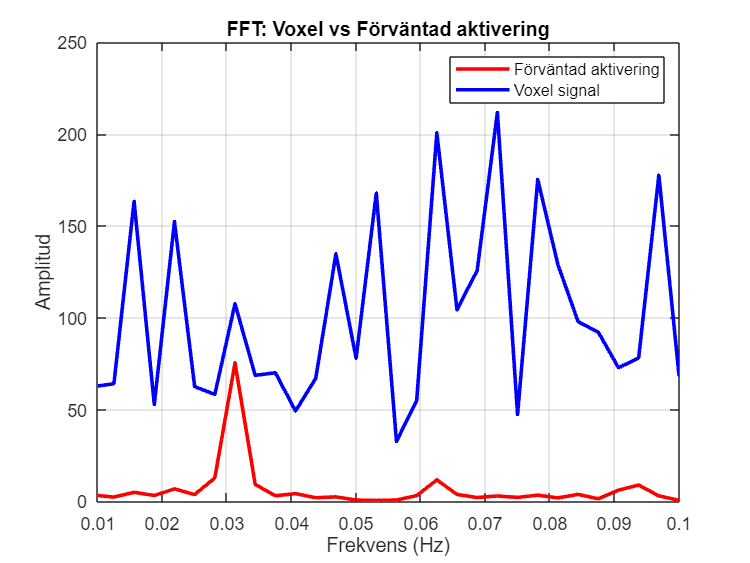

% Frekvensbaserad aktivering och voxel
dt = 2;                  % Tid mellan mätpunkter
Fs = 1/dt;               % sampling frekvens
T = length(activation_signal);

% FFT på aktiveringssignalen 
activation_fft = fft(activation_signal);
amp_activation = abs(activation_fft);
freq = (0:T-1)*(Fs/T);   % frekvensvektor

% Väljer en voxel att analysera
voxel_example = fMRI_matrix(5000,:); 
voxel_fft = fft(voxel_example);
amp_voxel = abs(voxel_fft);

% Plottar båda spektrumen
figure;
plot(freq, amp_activation, 'r', 'LineWidth', 2); hold on;
plot(freq, amp_voxel, 'b', 'LineWidth', 2);
xlabel('Frekvens (Hz)');
ylabel('Amplitud');
legend('Förväntad aktivering','Voxel signal');
title('FFT: Voxel vs Förväntad aktivering');
xlim([0.01 0.1]);  % relevant frekvensområde
grid on;


% Dynamisk frekvensbaserad korrelation 
dt = 2;               
Fs = 1/dt;            
[X,Y,Z,T] = size(img_filtered);
numVoxels = X*Y*Z;
fMRI_matrix = reshape(img_filtered, numVoxels, T);

% Hittar dominant frekvens i aktiveringssignal
activation_fft_full = fft(activation_signal);
amp_activation = abs(activation_fft_full);
[~, idx_dom] = max(amp_activation(2:floor(T/2)));
idx_dom = idx_dom + 1;  % justera index
dominant_freq = (idx_dom-1)*(Fs/T);
disp(['Dominant frekvens: ' num2str(dominant_freq) ' Hz']);

Dominant frekvens: 0.03125 Hz


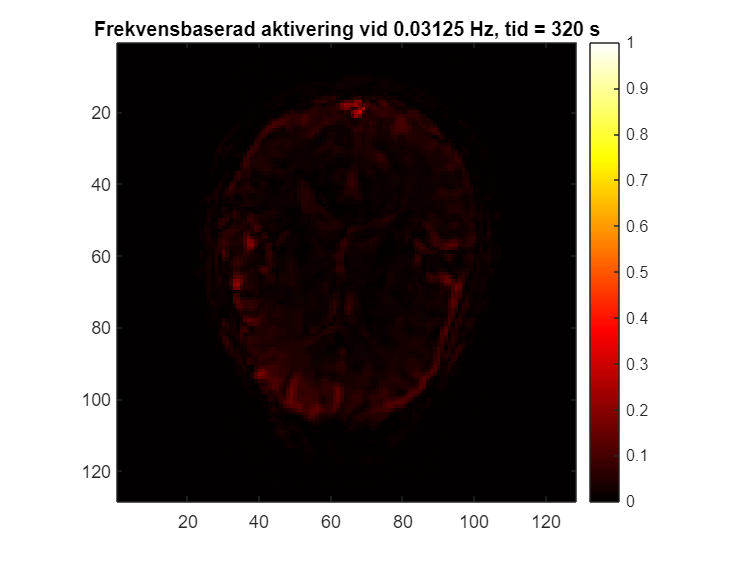


% Mittsnitt i z-led
z_mid = round(Z/2);

figure;

for t = 5:T
    % FFT på all voxlar fram till tid t
    voxel_fft = fft(fMRI_matrix(:,1:t), [], 2);
    
    % Tar amplituden vid dominant frekvens
    if idx_dom <= size(voxel_fft,2)
        voxel_amp_dom = abs(voxel_fft(:, idx_dom));
    else
        voxel_amp_dom = zeros(numVoxels,1);
    end
    
    % Normaliserar 
    voxel_amp_dom = voxel_amp_dom / max(voxel_amp_dom);
    
    % Omformar till 3D
    voxel_3D = reshape(voxel_amp_dom, X, Y, Z);
    
    % Visar mittsnitt
    imagesc(voxel_3D(:,:,z_mid));
    colormap hot;
    colorbar;
    axis image;
    caxis([0 1]);
    title(['Frekvensbaserad aktivering vid ', num2str(dominant_freq), ' Hz, tid = ' num2str(t*dt) ' s']);
    
    pause(0.05);
end

### **Diskussion**

I början av analysen såg vi inga förändringar mellan MRI-bilderna. Skillnaden är såpas liten att vi inte tydligt kan se den direkt och kan därför inte observera aktiveringen genom att enbart studera bildserien. 

Rörelsekorrigering och filtrering användes för att förbättra datakvalitén innan den statistiska analysen genomfördes. Filtreringen minskade högfrekvent brus i bilderna, och rörelsekorrigeringen minskar små rörelser mellan bilderna. Dessa steg är viktiga för att stabilisera signalen och göra den mer pålitlig.

När korrelationsanalysen genomfördes blev resultaten mycket tydlligare. I denna del jämfördes varje voxels tidsserie med den förväntande aktiveringssignalen, som skapades genom att konvolvera blockdesignen från mätningen med HRF-signalen. På detta sätt kunde de voxlar som följer samma tidsmönster som aktiveringen identifieras. Den skapta aktiveringskartan visade tydliga områden där korrelationen var hög, vilket tyder på att de aktiverats under finger-tapping-uppgiften. Där kunde vi även se att båda sidorna av hjärnan använts, vilket tyder på att båda händerna använts under aktiviteten. 

Histogrammet som togs fram i analysen visar att majoriteten av voxlarna har korrelationsvärden nära 0, vilket innebär att de inte är relaterade till den förväntade aktiveringen. Det var endast ett mindre antal voxlar som visade på hög korrelation, vilket visar att endast specifika delar av hjärnan är aktiva under uppgiften. Detta tyder på att metoden lyckats isolera de relevanta signalerna från MRI-datan.

För att komplettera analysen undersöktes voxelsignalerna även i frekvensdomänen. Genom att identifiera den dominerande frekvensen i aktiveringssignalen kunde signaler från voxlar jämföras utifrån deras frekvensinnehåll. Resultaten från frekvensanalysen visade dock mindre tydliga spatiala mönster jämfört med korrelationsanalysen. Detta kan bero på att metoden som analyserar frekvensen inte tar hänsyn till den exakta tidsstrukturen i aktiveringen, utan endast signalens frekvensinnehåll.

Sammanfattningsvis visar resultaten att denna typ av korrelationsanalys är en effektiv metod för att identifiera hjärnaktivitet i fMRI-data. 